# PHYS 3605W Exam 2

Cameron Laedtke

Problem 1

%Exam stuff
t = 10^-9.*[10, 20, 30, 40, 50, 60]' ;% seconds
V = 10.^-3.*[29.61, 21.16, 15.10, 10.78, 7.712, 5.496]'; % Volts
V_err = 10.^-3.*[0.15, 0.15, 0.15, 0.10, 0.05, 0.05]';
C = (2.17*10^-6)*10^-9*10^-2; % Ohms*seconds*meters
t_c = t./C;
ln_V = log(V);
ln_V_err = log(V_err);
fit_vals = myfit(t_c, ln_V, ln_V_err);
a = fit_vals(1,1)

a = -3.1827

b = fit_vals(1,2)

b = -7.3070e-10

ea = fit_vals(2,1)

ea = 8.3482

eb = fit_vals(2,2)

eb = 4.8444e-09

P = -b

P = 7.3070e-10

P =  7.307 $P=-b=\;\left(7\ldotp 31\pm 0\ldotp 48\right)*{10}^{-9}$

V_0 = exp(a)

V_0 = 0.0415

x = t_c

x = 	1.0e+09 *

    0.4608
    0.9217
    1.3825
    1.8433
    2.3041
    2.7650


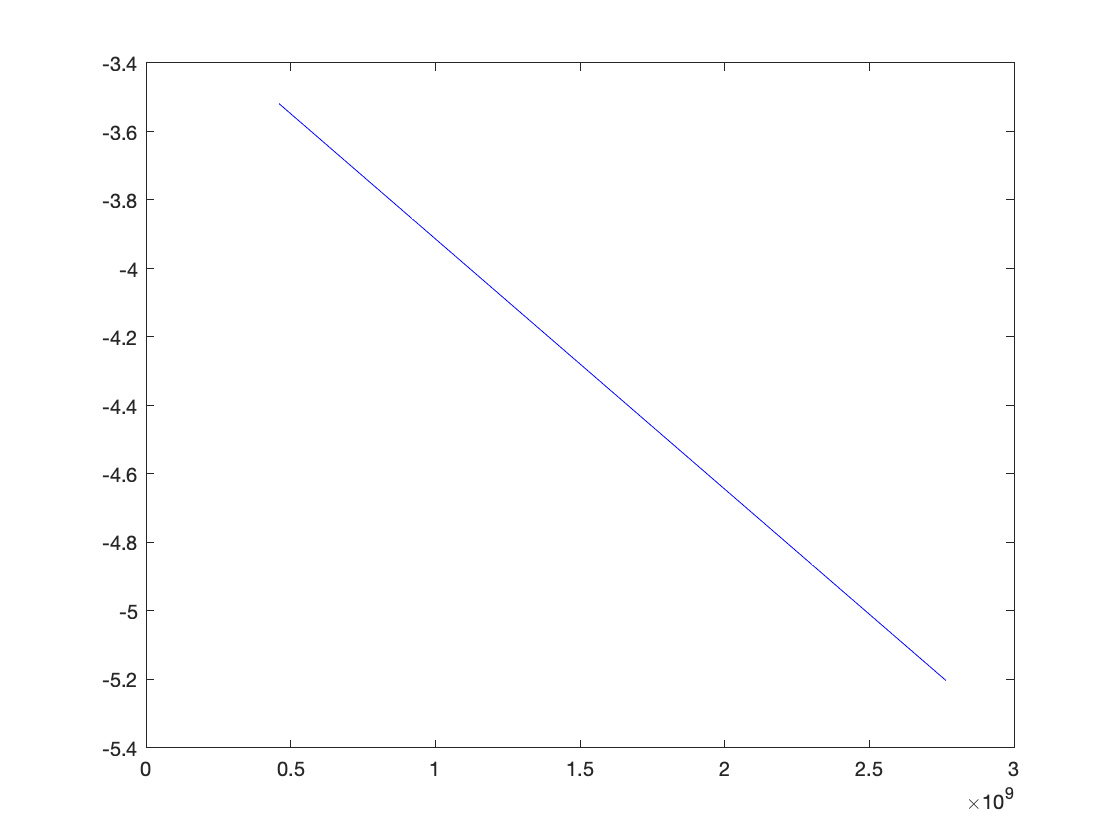

fit_y = a + x.*b;
plot(t_c, fit_y, 'b')

chi_data = getChi(ln_V, fit_y, ln_V_err)

chi_data = 	1.0e+-3 *

    0.0300    0.0000
   -0.0528    0.0000
    0.0254    0.0000
    0.0540    0.0000
   -0.1329    0.0000
    0.0719    0.0000


chi = chi_data(:,1)

chi = 	1.0e+-3 *

    0.0300
   -0.0528
    0.0254
    0.0540
   -0.1329
    0.0719


chi_squared = chi_data(:,2)

chi_squared = 	1.0e+-7 *

    0.0090
    0.0279
    0.0065
    0.0292
    0.1766
    0.0517


DOF = 4;
total_chi_2 = sum(chi_squared);
score = total_chi_2/DOF

score = 7.5220e-09

Problem 2

width = 0.0025;
n_particles = 100;
mu = 0.00125;
x = exprnd(mu, [n_particles,1]);
sd = std(x)

sd = 0.0012

function rval = myfit(x,y,ey)
  sx = sum(x ./ (ey .^ 2) );
  sy = sum(y ./ (ey .^ 2) );
  sxx = sum((x .* x) ./ (ey .^ 2) );
  sxy = sum((x .* y) ./ (ey .^ 2) );
  s = sum(1 ./ (ey .^ 2) );
  delta=sxx*s-sx*sx;
  a=(sxx*sy-sx*sxy)/delta;
  ea=sqrt(sxx/delta);
  b=(s*sxy-sx*sy)/delta;
  eb=sqrt(s/delta);
  rval=[ a, b ; ea, eb];
end

function chi_vals = getChi(y, fit_y, y_err)
   chi = (y - fit_y)./(y_err);
   chi2 = chi.^2;
   chi_vals = [chi, chi2];
end